clc;
clear;
close all;

%% Define Helper Functions

% Function: Vector field f1 for Delta_1
function vec = f1_D1(x)
    vec = [1; 0; x(1) + x(2)];
end

% Function: Vector field f2 for Delta_1
function vec = f2_D1(x)
    vec = [x(1); 0; x(2)];
end

% Function: Vector field f1 for Delta_2
function vec = f1_D2(x)
    vec = [x(1); x(2); x(3)];
end

% Function: Vector field f2 for Delta_2
function vec = f2_D2(x)
    vec = [0; 0; 1];
end

% Function: Compute the rank of the span of two vector fields
function r = computeRank(f1, f2, x)
    spanMatrix = [f1(x), f2(x)];
    r = rank(spanMatrix);
end

% Function: Compute the Lie bracket of two vector fields
function lb = lieBracket(f1, f2, x)
    % Evaluate the vector fields
    v1 = f1(x);
    v2 = f2(x);
    % Compute the Lie bracket
    lb = [ ...
        v1(2) * v2(3) - v1(3) * v2(2);
        v1(3) * v2(1) - v1(1) * v2(3);
        v1(1) * v2(2) - v1(2) * v2(1)];
end

% Function: Check if Lie bracket lies in the span
function isInvolutive = checkInvolutive(f1, f2, x)
    spanMatrix = [f1(x), f2(x)];
    lb = lieBracket(f1, f2, x);
    combinedMatrix = [spanMatrix, lb];
    % If rank doesn't increase after adding the Lie bracket, it's involutive
    isInvolutive = (rank(combinedMatrix) == size(spanMatrix, 2));
end

%% Test Points and Results
x_test = [1; 1; 1]; % Example test point

% Results for Delta_1
disp('--- Delta_1 Results ---');

--- Delta_1 Results ---


disp(['Rank at x = [1, 1, 1]: ', num2str(computeRank(@f1_D1, @f2_D1, x_test))]);

Rank at x = [1, 1, 1]: 2


disp(['Lie Bracket at x = [1, 1, 1]: ', mat2str(lieBracket(@f1_D1, @f2_D1, x_test))]);

Lie Bracket at x = [1, 1, 1]: [0;1;0]


disp(['Involutive: ', num2str(checkInvolutive(@f1_D1, @f2_D1, x_test))]);

Involutive: 0



% Results for Delta_2
disp('--- Delta_2 Results ---');

--- Delta_2 Results ---


disp(['Rank at x = [1, 1, 1]: ', num2str(computeRank(@f1_D2, @f2_D2, x_test))]);

Rank at x = [1, 1, 1]: 2


disp(['Lie Bracket at x = [1, 1, 1]: ', mat2str(lieBracket(@f1_D2, @f2_D2, x_test))]);

Lie Bracket at x = [1, 1, 1]: [1;-1;0]


disp(['Involutive: ', num2str(checkInvolutive(@f1_D2, @f2_D2, x_test))]);

Involutive: 0


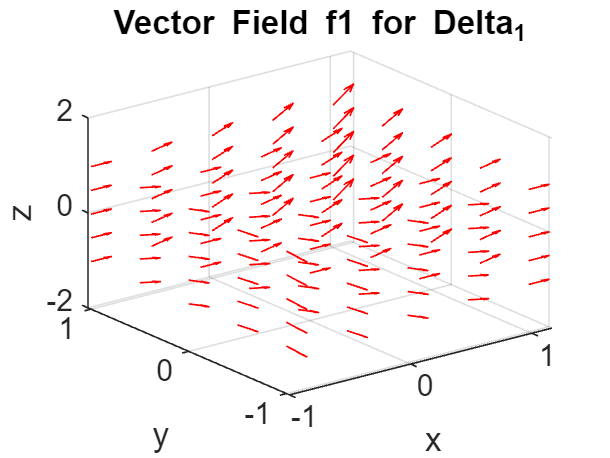


%% Visualization of Vector Fields and Lie Brackets
[x, y, z] = meshgrid(-1:0.5:1, -1:0.5:1, -1:0.5:1);

% Delta_1: Vector Field f1
u = ones(size(x));
v = zeros(size(x));
w = x + y;

figure;
quiver3(x, y, z, u, v, w, 'r');
title('Vector Field f1 for Delta_1');
xlabel('x'); ylabel('y'); zlabel('z');
grid on;

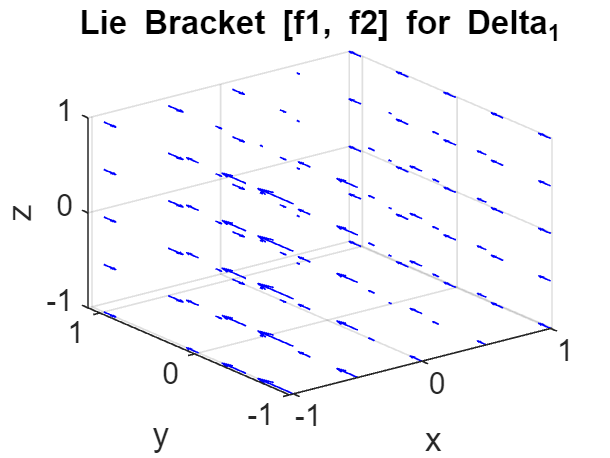


% Delta_1: Lie Bracket [f1, f2]
lb_u = zeros(size(x));
lb_v = x.^2 - y + x.*y;
lb_w = zeros(size(x));

figure;
quiver3(x, y, z, lb_u, lb_v, lb_w, 'b');
title('Lie Bracket [f1, f2] for Delta_1');
xlabel('x'); ylabel('y'); zlabel('z');
grid on;

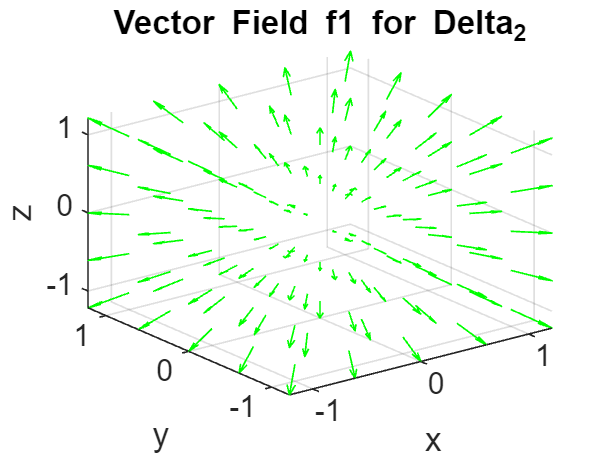


% Delta_2: Vector Field f1
u = x;
v = y;
w = z;

figure;
quiver3(x, y, z, u, v, w, 'g');
title('Vector Field f1 for Delta_2');
xlabel('x'); ylabel('y'); zlabel('z');
grid on;

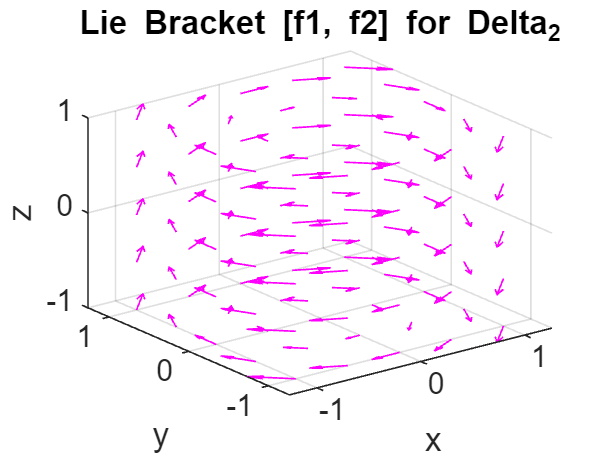


% Delta_2: Lie Bracket [f1, f2]
lb_u = y;
lb_v = -x;
lb_w = zeros(size(x));

figure;
quiver3(x, y, z, lb_u, lb_v, lb_w, 'm');
title('Lie Bracket [f1, f2] for Delta_2');
xlabel('x'); ylabel('y'); zlabel('z');
grid on;